# Dynamics Homework 1 Question 2

%clear

## f, h, and i)

mu = 0.0100

ml = 0.0200

dmm = 5

Current plot held


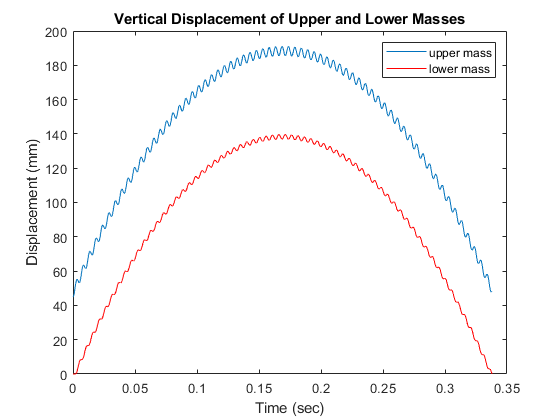

Current plot released


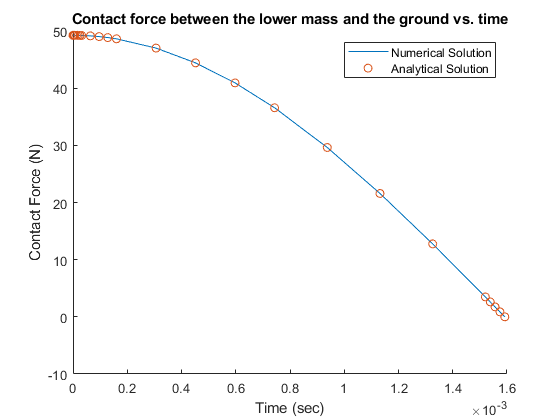

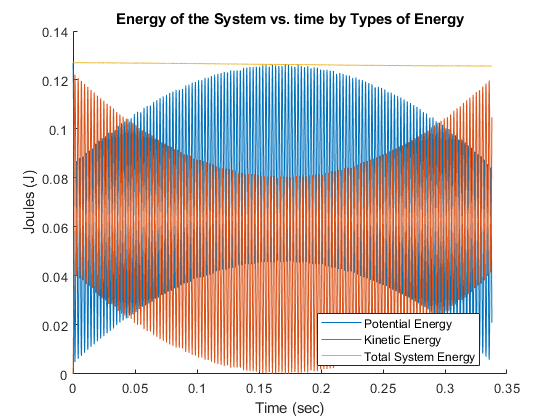

twomasshopper()

function [] = twomasshopper()

% Define system parameters
g = 9.81;                % gravitational acceleration in m/s^2
mugrams = 10;            % mugrams = upper mass in grams
mu = mugrams/1000        % upper mass in kg
mlgrams = 20;            % mlgrams = lower mass in grams
ml = mlgrams/1000        % lower mass in kg
k = 9810;                % k = linear spring stiffness in N/m
L0mm = 50;               % L0 = initial length of spring in mm   
L0 = L0mm/1000;          % unstretched spring length in meters
dmm = 5                  % d = initial displacement in mm; 
d = dmm/1000;            % initial displacement in m

omegau = sqrt(k/mu);
mtotal = mu + ml;

% Solve for phase 1 and phase 2 motion using separate ode45 calls 

% initial conditions for phase 1
% states: z1 = upper mass displacement, z2 = upper mass velocity, 
%         z3 = lower mass displacement, z4 = lower mass velocity
z1_0p1 = L0-d;
z2_0p1 = 0;
z3_0p1 = 0;
z4_0p1 = 0;
Z_0p1 = [z1_0p1, z2_0p1, z3_0p1, z4_0p1];

Tph1_span = [0, 20];       % define time span for phase 1 ode calc
options1 = odeset('Events', @event_stop1);
[tph1, yph1] = ode45(@phase1_fun, Tph1_span, Z_0p1, options1);

FN = ml*g + k* (L0-yph1(:,1)); % normal force on y_l in phase 1

% Initital conditions for phase 2 = end points for phase 1
Z_0p2 = [yph1(end,1), yph1(end,2), yph1(end,3), yph1(end,4)];
%
Tph2_span = [tph1(end), 50];

options2 = odeset('Events', @event_stop2);
[tph2, yph2] = ode45(@phase2_fun, Tph2_span, Z_0p2, options2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%energy calculations


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Check: Closed Form Calculations for Phase 1 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5
% Calculation for motion of center of mass for phase 2 only
% ycm = (mu*yu + ml*yl) / mtotal
% closed form solution = parabola

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plotting 
% combine phase 1 and phase 2 (column vectors)
%
figure (1)
plot ( [tph1;tph2], 1000*[yph1(:,1); yph2(:,1)]  )          %upper mass 
hold
plot ([tph1; tph2], 1000*[yph1(:,3); yph2(:,3)] , 'r' )     %lower mass 
% 
% t1 = linspace(0, 0.35, 500);
% yuph1_analytic = L0 - d + d - (mu*g/k)*(1-cos(sqrt(k/mu)* t1))     ;
% plot(t1, 1000*yuph1_analytic, '+g')         %analytic soln for y_u, in phase 1 

xlabel ('Time (sec)')
ylabel ('Displacement (mm)')
legend ('upper mass', 'lower mass') % 'analytic') % 'center of mass'
title  ('Vertical Displacement of Upper and Lower Masses')
%


% Contact force Plots
figure (2)
hold on
plot(tph1, FN)
FNAnalytical = ml*g + k*(d - (d -(mu*g/k))*(1 - cos(sqrt(k/mu)* tph1)));
plot(tph1, FNAnalytical, 'o')
hold
title('Contact force between the lower mass and the ground vs. time')
xlabel ('Time (sec)')
ylabel ('Contact Force (N)')
legend ('Numerical Solution', 'Analytical Solution')

% Energy Plots m*g*h
% Potential Energy mgh
PEu1 = mu*g*(yph1(:,1));
PEu2 = mu*g*(yph2(:,1));
PEl1 = ml*g*(yph1(:,3));
PEl2 = ml*g*(yph2(:,3));

PEu = [PEu1;PEu2];
PEl = [PEl1;PEl2];
PEt = PEu + PEl;

% Kinetic Energy 1/2 mv^2
KEu1 = 0.5*mu*(yph1(:,2)).^2;
KEu2 = 0.5*mu*(yph2(:,2)).^2;
KEl1 = 0.5*ml*(yph1(:,4)).^2;
KEl2 = 0.5*ml*(yph2(:,4)).^2;

KEu = [KEu1;KEu2];
KEl = [KEl1;KEl2];
KEt = KEu + KEl;

% Spring Elastic Energy 0.5*k*x^2
SpE1 = 0.5*k.*(L0-(yph1(:,1)-yph1(:,3))).^2;
SpE2 = 0.5*k.*(L0-(yph2(:,1)-yph2(:,3))).^2;
SpE = [SpE1;SpE2];

totalPE = PEt + SpE;
totalKE = KEt;
totalE = totalPE + totalKE;

figure (3)
hold on
plot([tph1;tph2],totalPE)
plot([tph1;tph2],totalKE)
plot([tph1;tph2],totalE)
legend('Potential Energy','Kinetic Energy','Total System Energy', 'Location',"best")
title('Energy of the System vs. time by Types of Energy')
xlabel ('Time (sec)')
ylabel ('Joules (J)')
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% function for phase 1 
function dzdtph1 = phase1_fun(T, Z)

% Z(1) = y_u, Z(2) = ydot_u, Z(3) = y_l, Z(4) = ydot_l
dz1dt = Z(2); % ADD EQN HERE  
dz2dt = k/mu * (L0 - (Z(1) - Z(3))) - g; % ADD EQN HERE 
dz3dt = 0;     % z3, z4 eqns are not needed but do fill the vector with zeros
dz4dt = 0;
%
dzdtph1 = [dz1dt;dz2dt;dz3dt;dz4dt];
%
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% function for phase 2 
function dxdtph2 = phase2_fun(T, Z)
%
% Z(1) = y_u, Z(2) = ydot_u, Z(3) = y_l, Z(4) = ydot_ld
%
dx1dt = Z(2); % ADD EQN HERE 
dx2dt = -g + (k/mu)*(L0 - (Z(1) - Z(3))); % ADD EQN HERE 
dx3dt = Z(4); % ADD EQN HERE 
dx4dt = -g - (k/ml)*(L0 - (Z(1) - Z(3))); % ADD EQN HERE 
%
dxdtph2 = [dx1dt;dx2dt;dx3dt;dx4dt];
%
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [eventvalue,stopthecalc,eventdir] = event_stop1(T,Z)
        % stop when FN = 0 (lower mass leaves the ground, normal force = 0)
        eventvalue  = ml*g + k* (L0-Z(1)); % FN; % ADD EQN HERE ;       % end when FN = 0
        stopthecalc = 1;                     % stop if event occurs
        eventdir    = -1;                    % dirction condition = dydt<0
end     
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [eventvalue,stopthecalc,eventdir] = event_stop2(T,Z)
        % stop when yl = 0 (lower mass hits the ground)
  
        eventvalue  = Z(3);  % end when yl hits ground (=0)
        stopthecalc =    1;  % stop if event occurs
        eventdir    =   -1;  % direction conditon = dydt<0
end      
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

end